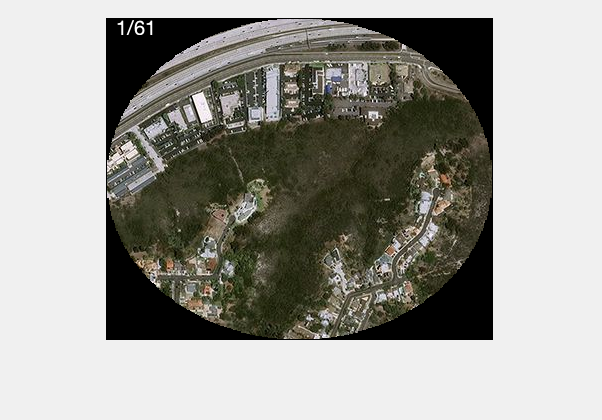

clc
clear all
close all

letter = "B";
directory = "Test Images/Snipped/"+letter+"/";
imagefiles = dir(directory);      
nfiles = length(imagefiles);    % Number of files found

% figure()
for ii=4:nfiles
   currentfilename = imagefiles(ii).name;
   currentimage = imread(directory+currentfilename, "png");
   images{ii - 2} = currentimage;
   [~,imageNames{ii - 2},~] = fileparts(currentfilename);
   % subplot(nfiles-3, 1, ii - 3);
   % imshow(images{ii - 3});
end

neworder = randperm(length(images));
for i=1:length(images)
    images2{i} = images{neworder(i)};
end
images = images2;

% images{1} = imread("Test Images/Snipped/A/A4.jpg");
% images{2} = imread("Test Images/Snipped/A/A7.jpg");
% images{3} = imread("Test Images/Snipped/A/A15.jpg");
% images{4} = imread("Test Images/Snipped/A/A12.jpg");
% images{5} = imread("Test Images/Snipped/A/A18.jpg");

% images{1} = imread("leftoriginal.png")
% images{2} = imread("leftleft.png")

% % right = imread("leftshifted.png");
% figure()
% imshow(images{1})
% imshow(images{2})

fig = figure;
set(gcf,'Visible','on');

out = images{1};
thresh = 0.0005;
speedthresh = 0.01;
stitched = zeros(length(images),1);
stitched(1)=1;
length(images);

pltanim(out,stitched);


end_early = false;
default_points = 0.5;
for j=1:length(images)
    disp(j)
    points=default_points;
    finished = false;
    while ~finished
        confidences = zeros(length(images),3);
        for i=1:length(images)
            if stitched(i)==0
                [final_slope, final_length, final_delta_x, final_delta_y, final_confidence] = custom_sift(out, images{i}, 8, points, true);
                confidences(i,:)=[final_confidence,final_delta_x,final_delta_y];
                if confidences(i,1)>=speedthresh
                    break
                end
            end
        end
        if sum(confidences(:,1)>=thresh)~=0
            [v,ind]=max(confidences(:,1));
            disp(v)
            [out, valid] = merge_images(out, images{ind}, round(-confidences(ind,2)), round(-confidences(ind,3)), 25, 1);
            % imwrite(out, "Output/"+letter+"/Run3_Stitch"+sum(stitched)+"_Conf"+round(v*10000)+".png");
            if ~valid
                points=points+0.5
                if points>=3.5
                    finished=true;
                    end_early=true;
                end
            else
                points=default_points;
                stitched(ind)=1;
                pltanim(out,stitched);
            end
        else
            if points>=2
                finished=true;
                end_early=true;
            else
                points=points+0.5
                default_points=default_points+0.25
            end
        end
    end
    if end_early
        break
    end
end

     1



    0.1167



Not enough input arguments.

Error in merge_images (line 59)
    if ~suppress

sum(stitched)
imageNames(~stitched)
pltanim(out,stitched);
text(10,30,"Done!","Color",[1,1,1]);
imwrite(out, "Output/"+letter+"/"+rand()+".png");

function [] = pltanim(out, stitched)
        imshow(out);
        text(10,10,""+sum(stitched)+"/"+length(stitched),"Color",[1,1,1]);
        drawnow();
end